## Generate all the IDP and PLV value if required

PatientIDs = {'P1','P2','P3','P4','P5'}; 

GenerateIPD_PLVTables(PatientIDs); 

  Columns 1 through 11

    {'Fz-FC3'}    {'Fz-FC1'}    {'Fz-FCz'}    {'Fz-FC2'}    {'Fz-FC4'}    {'Fz-C3'}    {'Fz-C1'}    {'Fz-C2'}    {'Fz-C4'}    {'Fz-CP3'}    {'Fz-CP1'}

  Columns 12 through 21

    {'Fz-CPz'}    {'Fz-CP2'}    {'Fz-CP4'}    {'FC3-FC1'}    {'FC3-FCz'}    {'FC3-FC2'}    {'FC3-FC4'}    {'FC3-C3'}    {'FC3-C1'}    {'FC3-C2'}

  Columns 22 through 31

    {'FC3-C4'}    {'FC3-CP3'}    {'FC3-CP1'}    {'FC3-CPz'}    {'FC3-CP2'}    {'FC3-CP4'}    {'FC1-FCz'}    {'FC1-FC2'}    {'FC1-FC4'}    {'FC1-C3'}

  Columns 32 through 41

    {'FC1-C1'}    {'FC1-C2'}    {'FC1-C4'}    {'FC1-CP3'}    {'FC1-CP1'}    {'FC1-CPz'}    {'FC1-CP2'}    {'FC1-CP4'}    {'FCz-FC2'}    {'FCz-FC4'}

  Columns 42 through 51

    {'FCz-C3'}    {'FCz-C1'}    {'FCz-C2'}    {'FCz-C4'}    {'FCz-CP3'}    {'FCz-CP1'}    {'FCz-CPz'}    {'FCz-CP2'}    {'FCz-CP4'}    {'FC2-FC4'}

  Columns 52 through 61

    {'FC2-C3'}    {'FC2-C1'}    {'FC2-C2'}    {'FC2-C4'}    {'FC2-CP3'}    {'FC2-CP1'}    {'FC2-CPz'}    {

pop_loadset(): loading file C:\University\BCIWristIdentification2\OwnData\P3RH\P3RH_epochs_filt2_ICAEOG_ERDS.set ...
Reading float file 'C:\University\BCIWristIdentification2\OwnData\P3RH\P3RH_epochs_filt2_ICAEOG_ERDS.fdt'...
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Creating a new ALLEEG dataset 1
Removing 100 trial(s)...
Pop_select: removing 405 unreferenced events
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Creating a new ALLEEG dataset 2
Scaling components to RMS microvolt
channel or IC number: 1
channel or IC number: 2
channel or IC number: 3
channel or IC number: 4
channel or IC number: 5
channel or IC number: 6
channel or IC number: 7
channel or IC number: 8
channel or IC number: 9
channel or IC number: 10
channel or IC number: 

## Load a specific patients data to allow Classification learn to Use specific data 

PatientID = "P1";
if ispc
        % For Windows
        % Construct the file path using sprintf
        IPDTable = load(sprintf('..\\OwnResults\\%sRH\\MatlabGeneratedData\\IPDTable.mat', PatientID)).IPDTable;
        PLVTable = load(sprintf('..\\OwnResults\\%sRH\\MatlabGeneratedData\\PLVTable.mat', PatientID)).PLVTable;
        IPD_PLVTable = load(sprintf('..\\OwnResults\\%sRH\\MatlabGeneratedData\\IPD_PLVTable.mat', PatientID)).IPD_PLVTable;
    elseif ismac
        % Prompt the user to load a .mat file containing the data
        [file, path] = uigetfile('*.mat', 'Select the MATLAB data file');
        if isequal(file, 0)
            disp('User canceled the operation');
            return;
        end
end

## ANOVA one way 

columnNames = IPDTable.Properties.VariableNames;
predictorNames = columnNames(1,1:end-1);
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];


predictors = IPDTable(:, predictorNames);
response = IPDTable.Class;

predictors = standardizeMissing(predictors, {Inf, -Inf});
predictorMatrix = normalize(predictors);
newPredictorMatrix = zeros(size(predictorMatrix));
for i = 1:size(predictorMatrix, 2)
    if isCategoricalPredictor(i)
        newPredictorMatrix(:,i) = grp2idx(predictorMatrix{:,i});
    else
        newPredictorMatrix(:,i) = predictorMatrix{:,i};
    end
end
predictorMatrix = newPredictorMatrix;
responseVector = grp2idx(response);

% Rank features using ANOVA algorithm
for i = 1:size(predictorMatrix, 2)
    pValues(i) = anova1(...
        predictorMatrix(:,i), ...
        responseVector, ...
        'off');
end
[~,featureIndex] = sort(-log(pValues), 'descend');
numFeaturesToKeep = 50;
includedPredictorNames = predictors.Properties.VariableNames(featureIndex(1:numFeaturesToKeep));
predictors = predictors(:,includedPredictorNames);

SVMModel = fitcsvm(predictors, response, 'KernelFunction', 'rbf');

Training Accuracy: 77%


Test Accuracy: 77%


## Hyperparameter tuning

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |        0.42 |     0.31818 |        0.42 |        0.42 |    0.0027412 |       57.206 |
|    2 | Accept |         0.5 |     0.23023 |        0.42 |       0.425 |    0.0029834 |     0.046824 |
|    3 | Accept |         0.5 |     0.18996 |        0.42 |     0.42001 |        60.95 |      0.62979 |
|    4 | Accept |        0.43 |     0.20932 |        0.42 |     0.42001 |       4.5147 |       202.28 |
|    5 | Accept |        0.52 |      0.1786 |        0.42 |     0.42001 |       144.69 |       25.194 |
|    6 | Accept |        0.43 |     0.10606 |        0.42 |     

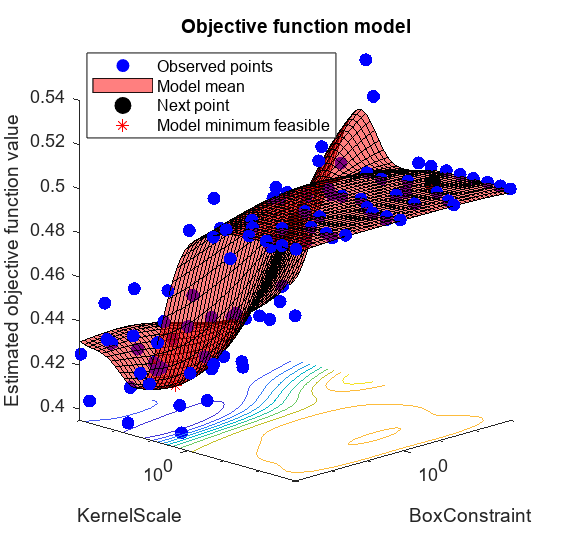

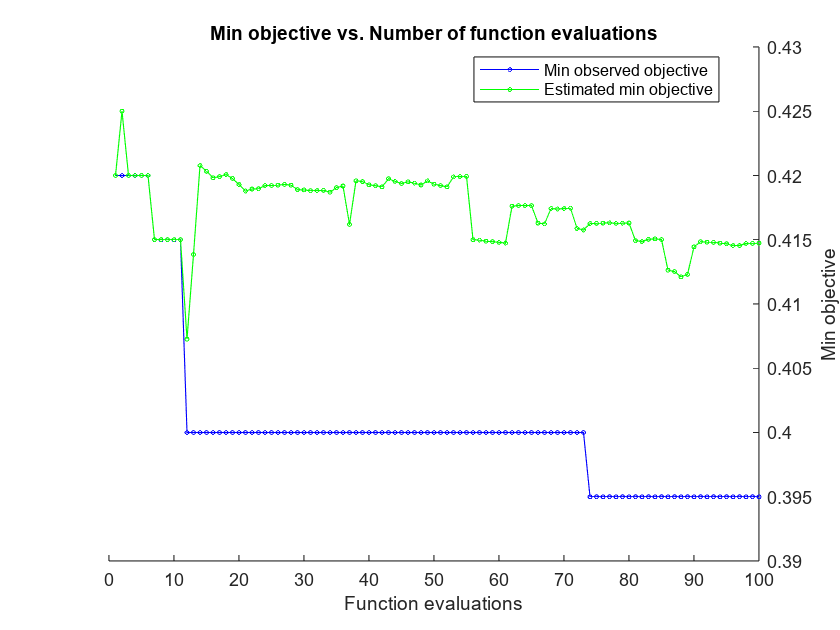


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 89.7556 seconds
Total objective function evaluation time: 11.9505

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

      0.0062209        9.3366   

Observed objective function value = 0.395
Estimated objective function value = 0.43107
Function evaluation time = 0.097774

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

      0.0067787         50.76   

Estimated objective function value = 0.41473
Estimated function evaluation time = 0.11768



% Define the SVM model function for Bayesian Optimization
svmModel = @(params)fitcsvm(predictors, response, ...
    'KernelFunction', 'rbf', ...
    'BoxConstraint', params.BoxConstraint, ...
    'KernelScale', params.KernelScale, ...
    'Standardize', true, ...
    'CrossVal', 'on', ...
    'KFold', 10);

% Define the optimization variables
optimVars = [
    optimizableVariable('BoxConstraint', [1e-3, 1e3], 'Transform', 'log');
    optimizableVariable('KernelScale', [1e-3, 1e3], 'Transform', 'log')
    ];

% Define the objective function for Bayesian optimization
minfn = @(params)kfoldLoss(svmModel(params));

% Run Bayesian Optimization
results = bayesopt(minfn, optimVars, ...
    'MaxObjectiveEvaluations', 100, ...
    'Verbose', 1, ...
    'IsObjectiveDeterministic', false, ...
    'AcquisitionFunctionName', 'expected-improvement-plus');


% Extract the best hyperparameters
bestParams = bestPoint(results);

% Train the final SVM model with the best hyperparameters on the training set
% finalSVMModel = fitcsvm(X_train, Y_train, ...
%     'KernelFunction', 'rbf', ...
%     'BoxConstraint', bestParams.BoxConstraint, ...
%     'KernelScale', bestParams.KernelScale, ...
%     'Standardize', true);

## Stratified K-fold cross-validation

numFolds = 10; % Number of folds for cross-validation
rng(1); % Fixed seed for consistent results

% Use the full combined table for cross-validation
xtrain = predictors;
ytrain = response;
cvPartition = cvpartition(ytrain, 'KFold', numFolds, 'Stratify', true);


foldAccuracy = zeros(numFolds, 1);

for fold = 1:numFolds
    trainIndices = cvPartition.training(fold);
    testIndices = cvPartition.test(fold);

    XtrainFold = xtrain(trainIndices, :);
    YtrainFold = ytrain(trainIndices);
    XtestFold = xtrain(testIndices, :);
    YtestFold = ytrain(testIndices);

    SVMModel = fitcsvm(XtrainFold, YtrainFold, ...
    'KernelFunction', 'rbf', ...
    'BoxConstraint', bestParams.BoxConstraint, ...
    'KernelScale', bestParams.KernelScale, ...
    'Standardize', true);

    YtestPred = predict(SVMModel, XtestFold);

    foldAccuracy(fold) = sum(YtestPred == YtestFold) / length(YtestFold);
end

meanAccuracy = mean(foldAccuracy);
disp(['Average Cross-Validation Accuracy: ', num2str(meanAccuracy * 100), '%']);

Average Cross-Validation Accuracy: 56.5%
